# Transformada de fourier

## Ploteo del ejercicio a mano

syms omega

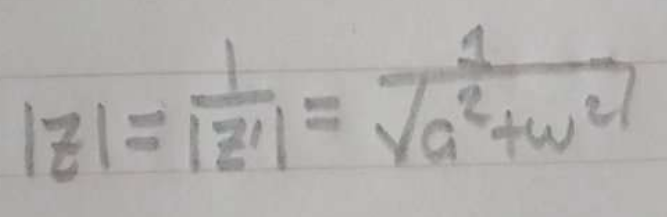 

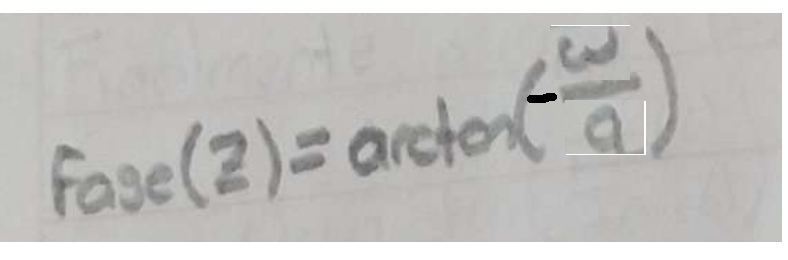

Propiedad de Adrian

a=2;
x_mag=1/(a^2+omega^2)

$$x\_mag = \frac{1}{\omega^{2}+4}$$

x_ph=atan(-omega/a)

$$x\_ph = -\mathrm{atan}\left(\frac{\omega }{2}\right)$$

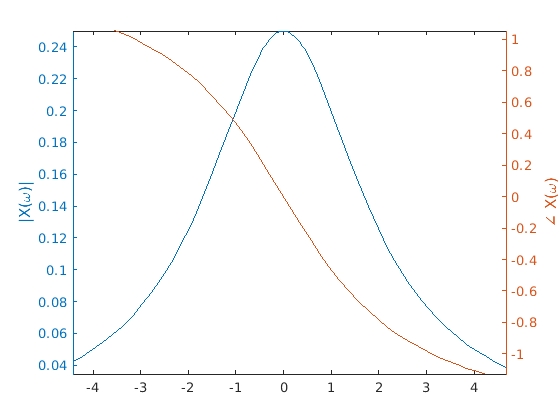



figure
yyaxis left
fplot(x_mag)
ylabel("|X(\omega)|")
yyaxis right
fplot(x_ph)
ylabel("\angle X(\omega)")

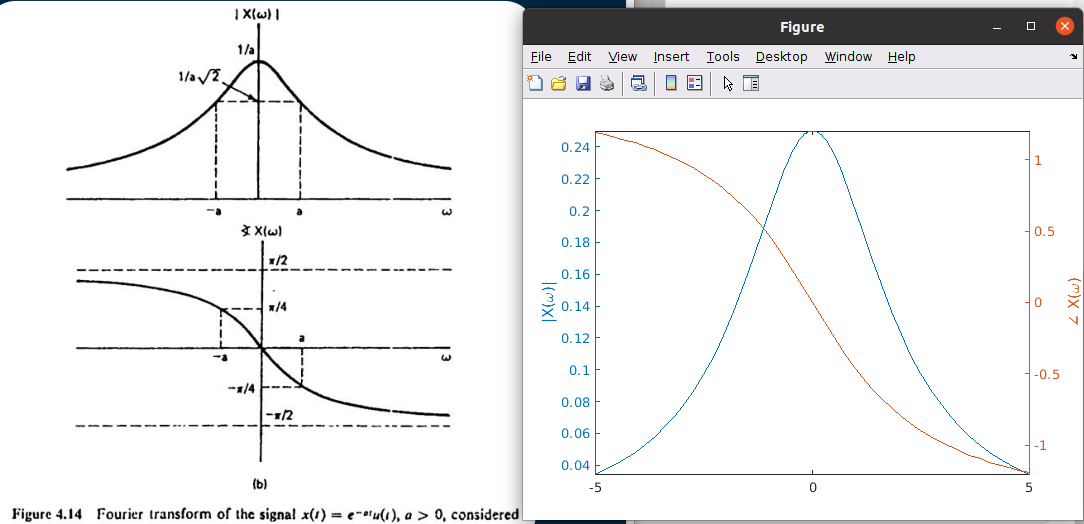

## Segundo ejercicio

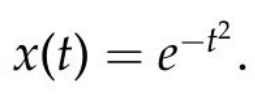

$X(\omega)$ 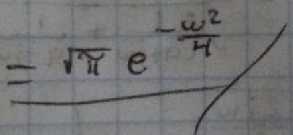 

Propiedad de Erik

- Plotear

- Usar la función fourier y comparar resultados

syms t omega
x=exp(-t^2)

$$x = {\mathrm{e}}^{-t^{2}}$$

X=sqrt(pi)*exp(-omega^2/4)

$$X = \frac{3991211251234741\,{\mathrm{e}}^{-\frac{\omega^{2}}{4}}}{2251799813685248}$$

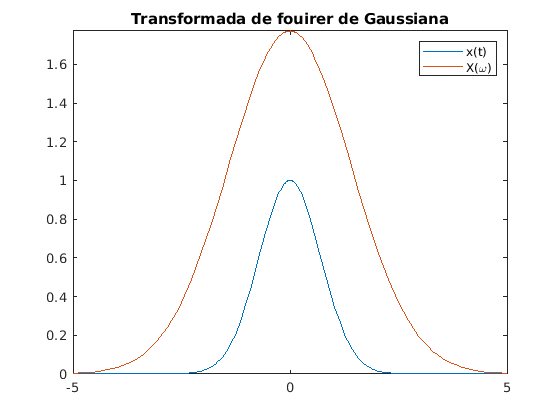


figure
fplot(x)
hold on
fplot(X)
hold off
legend("x(t)","X(\omega)")
title("Transformada de fouirer de Gaussiana")


% Usando la función fourier
X_sym=fourier(x)

$$X\_sym = \sqrt{\pi }\,{\mathrm{e}}^{-\frac{w^{2}}{4}}$$

## Inversa

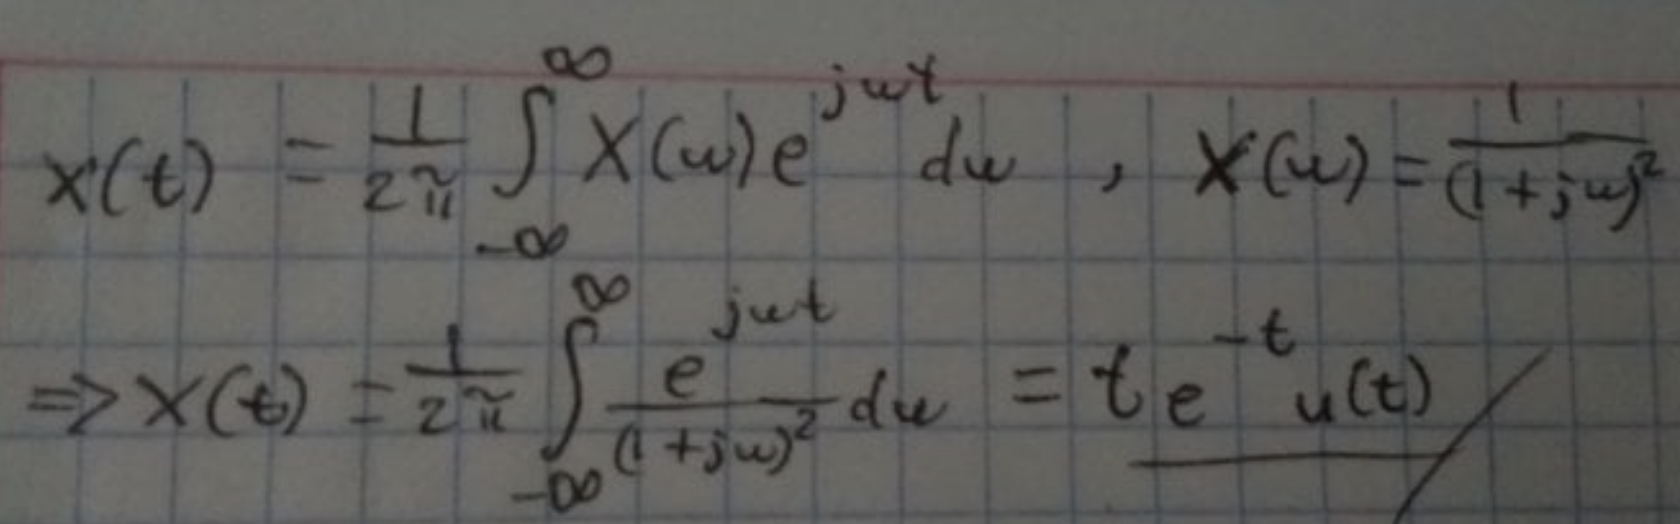

Propiedad de Erik

%Plotear resultado
x=t*exp(-t)*heaviside(t)

$$x = t\,{\mathrm{e}}^{-t}\,\mathrm{heaviside}\left(t\right)$$

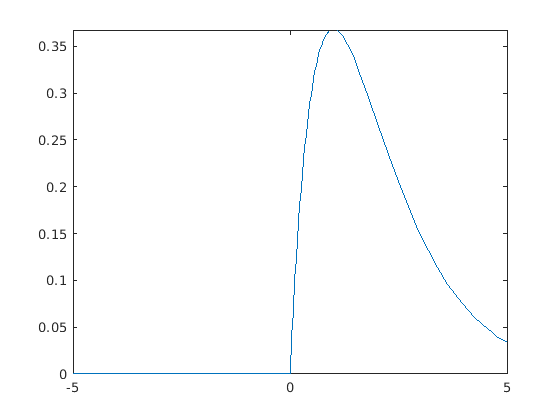

figure
fplot(x)


%Usar función ifourier
x_sym=ifourier(1/(1+1j*omega)^2,omega)

$$x\_sym = \frac{\pi \,\omega \,{\mathrm{e}}^{-\omega }+\pi \,\omega \,{\mathrm{e}}^{-\omega }\,\mathrm{sign}\left(\omega \right)}{2\,\pi }$$

figure
fplot(x_sym)